# Código Principal

## Configuración general:

Configuración del archivo:

clear; close all; clc;
%addpath([pwd,'\functions']);
%addpath([pwd,'\Resultados']);
excel = 'trayectorias_FW_1.xlsx'; %Cambiar el nombre de excel de salida del archivo
tiempos_de_calculo = struct();
% Guardar el tiempo de inicio
tiempos_de_calculo.tiempo_de_inicio = datetime('now');

Invocamos a la funcion con los valores de salida de los resultados:

var_sal = variables_de_salida(excel);

Invocamos a la funcion con los valores de inicio:

var_ini = variables_de_inicio(excel); %variables de seteo del programa

Invocamos a la funcion con la configuración de la máquina:

var_maq = variables_de_la_maquina(excel);

## Datos específicos del Estudio Nº 1:

A las variables iniciales de inicio les tenemos que modificar las siguientes propiedades:

- Ancho de filamento: b = 5mm

- Radio del mandril en el extremo izquierdo: rim = 30 mm

- Radio del mandril en el extremo derecho: rfm = 50mm

- Coordenada del extremo izquierdo del mandril: zim = 0mm

- Coordenada del extremo izquierdo del área de bobinado geodésico: zi = 100 mm

- Coordenada del extremo derecho del área de bobinado geodésico: zfg = 300mm

- Coordenada del extremo derecho del mandril: zfm = 600mm

- Ángulo de bobinado: alfainicio = 75º

- Parámetro λ: lambda1 = 0,14

var_ini.b = 6;
var_ini.rim = 75;
var_ini.rfm = 75;
var_ini.zim = -500;
var_ini.zi = 0;
var_ini.zfg = 300;
var_ini.zfm = 1000;
var_ini.alfainicio = 45;
var_ini.lambda1 = 0.14;
sobreescribir_variables_de_inicio(var_ini, excel);

## Calculos iniciales:

vector_calculos_iniciales = calculos_iniciales(var_ini, excel);

## Generación del mandril y su gráfico:

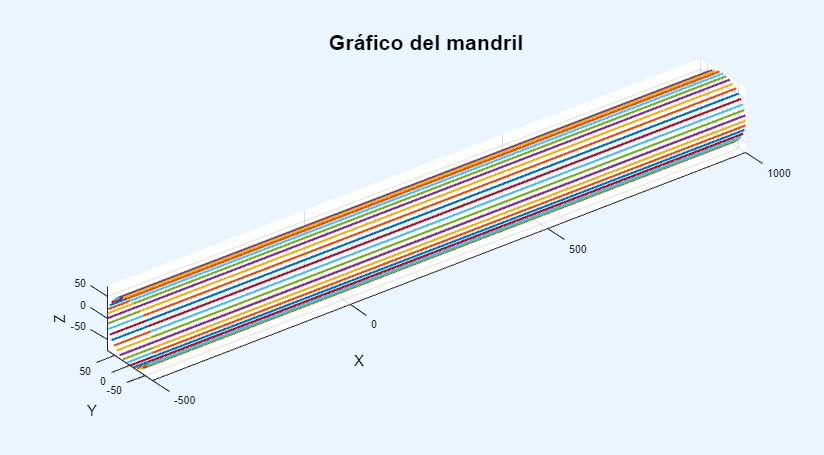

vector_mandril = generacion_del_mandril(var_ini, vector_calculos_iniciales, excel);
graficar(vector_mandril, 'Gráfico del mandril', 1, 'mandril.png');

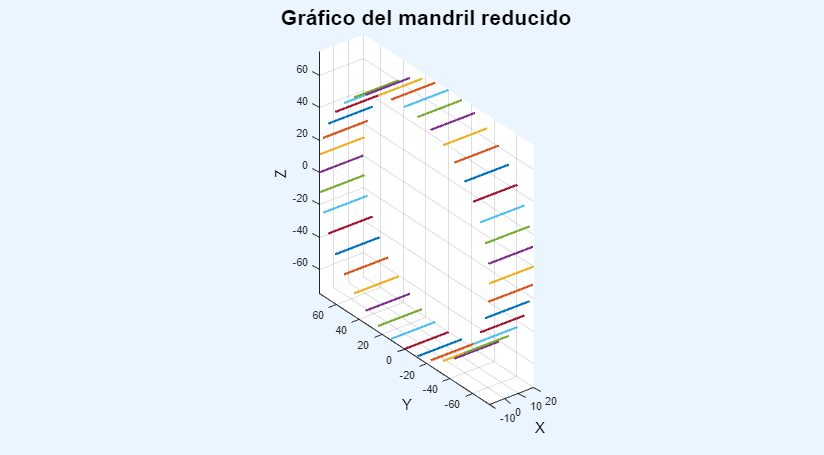

graficar(vector_mandril, 'Gráfico del mandril reducido', 50, 'mandril_reducido.png');

## Generación de la hélice de la ida y su gráfico:

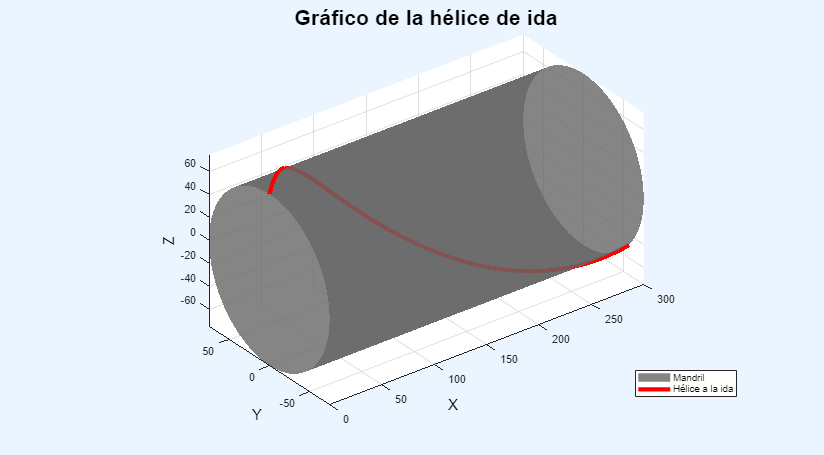

vector_helice_ida = generador_helice_ida(var_ini, vector_calculos_iniciales, excel);
grafica_multiple_1 = struct( ...
    'X1', vector_helice_ida.X, ...
    'Y1', vector_helice_ida.Y, ...
    'Z1', vector_helice_ida.Z);
graficas_multiples(grafica_multiple_1, 'Gráfico de la hélice de ida', {'Hélice a la ida'}, var_ini, ... 
    'helice_ida.png'); clear grafica_multiple_1;

## Generación de la trayectoria de retorno de la ida y su gráfico:

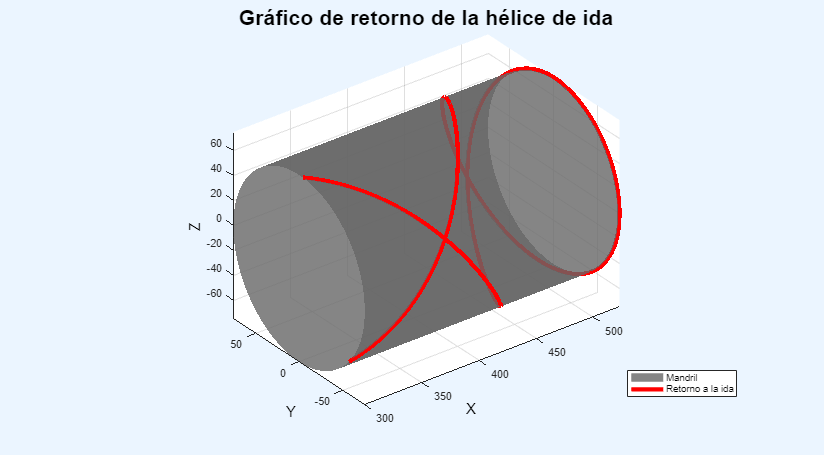

vector_retorno_ida = retorno_ida(var_ini, vector_calculos_iniciales, vector_mandril, vector_helice_ida, excel);
grafica_multiple_2 = struct( ...
    'X1', vector_retorno_ida.X, ...
    'Y1', vector_retorno_ida.Y, ...
    'Z1', vector_retorno_ida.Z);
graficas_multiples(grafica_multiple_2, 'Gráfico de retorno de la hélice de ida', {'Retorno a la ida'}, var_ini, ...
    'retorno_ida.png'); clear grafica_multiple_2;

Graficos de la curva de ida y del retorno de la ida:

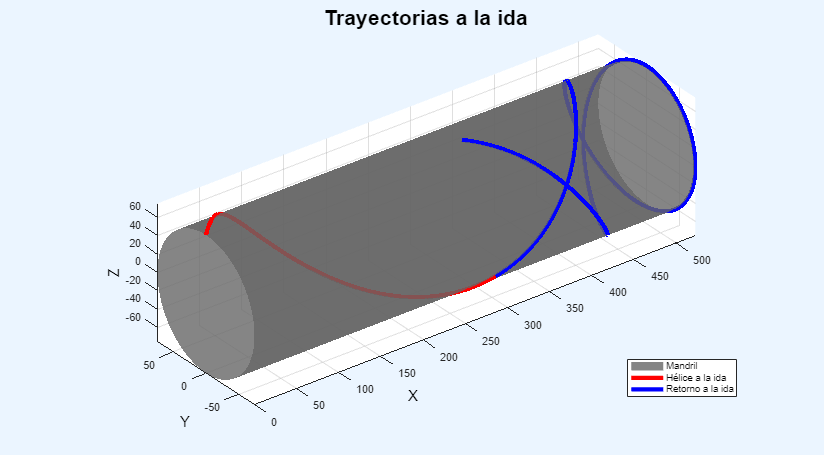

grafica_multiple_3 = struct( ...
    'X1', vector_helice_ida.X, ...
    'Y1', vector_helice_ida.Y, ...
    'Z1', vector_helice_ida.Z, ...
    'X2', vector_retorno_ida.X, ...
    'Y2', vector_retorno_ida.Y, ...
    'Z2', vector_retorno_ida.Z);
graficas_multiples(grafica_multiple_3, 'Trayectorias a la ida', {'Hélice a la ida', 'Retorno a la ida'}, var_ini, ...
    'helice&retorno_ida.png'); clear grafica_multiple_3;

## Generación de la trayectoria de la vuelta y su gráfico:

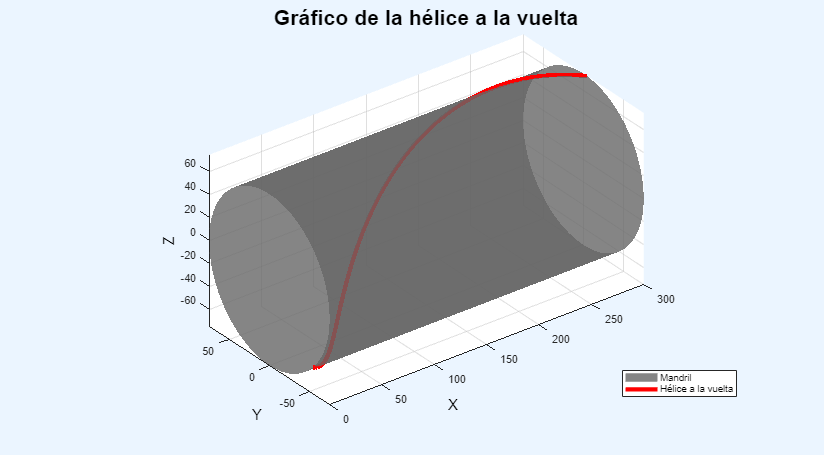

vector_helice_vuelta = generador_helice_vuelta(var_ini, vector_retorno_ida, vector_helice_ida, vector_calculos_iniciales, excel);
grafica_multiple_4 = struct( ...
    'X1', vector_helice_vuelta.X, ...
    'Y1', vector_helice_vuelta.Y, ...
    'Z1', vector_helice_vuelta.Z);
graficas_multiples(grafica_multiple_4, 'Gráfico de la hélice a la vuelta', {'Hélice a la vuelta'}, var_ini, ...
    'helice_vuelta.png'); clear grafica_multiple_4;

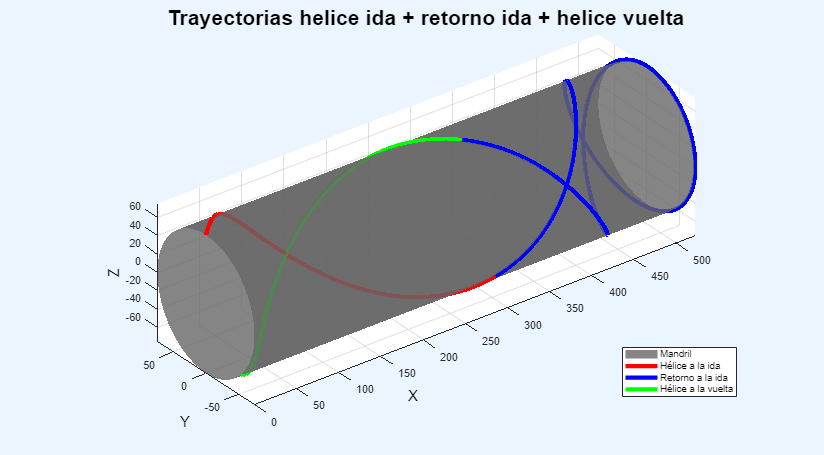

grafica_multiple_5 = struct( ...
    'X1', vector_helice_ida.X, ...
    'Y1', vector_helice_ida.Y, ...
    'Z1', vector_helice_ida.Z, ...
    'X2', vector_retorno_ida.X, ...
    'Y2', vector_retorno_ida.Y, ...
    'Z2', vector_retorno_ida.Z, ...
    'X3', vector_helice_vuelta.X, ...
    'Y3', vector_helice_vuelta.Y, ...
    'Z3', vector_helice_vuelta.Z);
graficas_multiples(grafica_multiple_5, 'Trayectorias helice ida + retorno ida + helice vuelta', {'Hélice a la ida', ...
    'Retorno a la ida', 'Hélice a la vuelta'}, var_ini, 'helice_ida&retorno_ida&helice_vuelta.png'); clear grafica_multiple_5;

## Generación de la trayectoria de retorno de la vuelta y su gráfico:

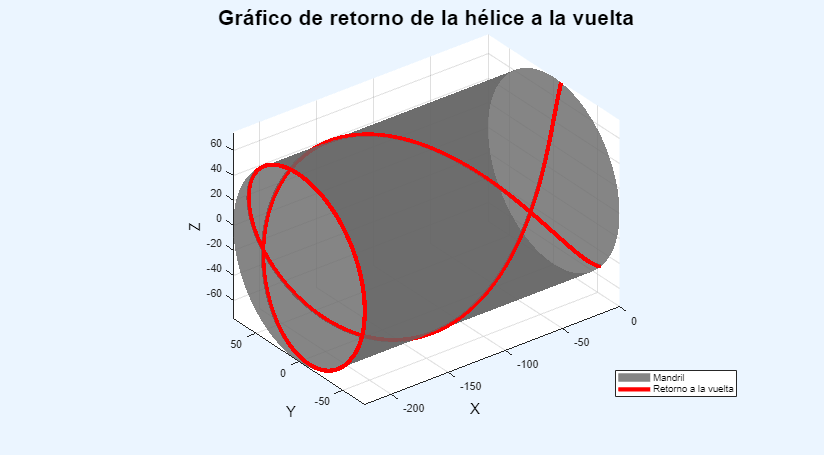

vector_retorno_vuelta = retorno_vuelta(var_ini, vector_calculos_iniciales, vector_helice_ida, vector_retorno_ida, ...
    vector_helice_vuelta, excel);
grafica_multiple_6 = struct( ...
    'X1', vector_retorno_vuelta.X, ...
    'Y1', vector_retorno_vuelta.Y, ...
    'Z1', vector_retorno_vuelta.Z);
graficas_multiples(grafica_multiple_6, 'Gráfico de retorno de la hélice a la vuelta', {'Retorno a la vuelta'}, var_ini, ...
    'retorno_vuelta.png'); clear grafica_multiple_6;

## Generación de las trayectorias de un ciclo completo y su gráfico:

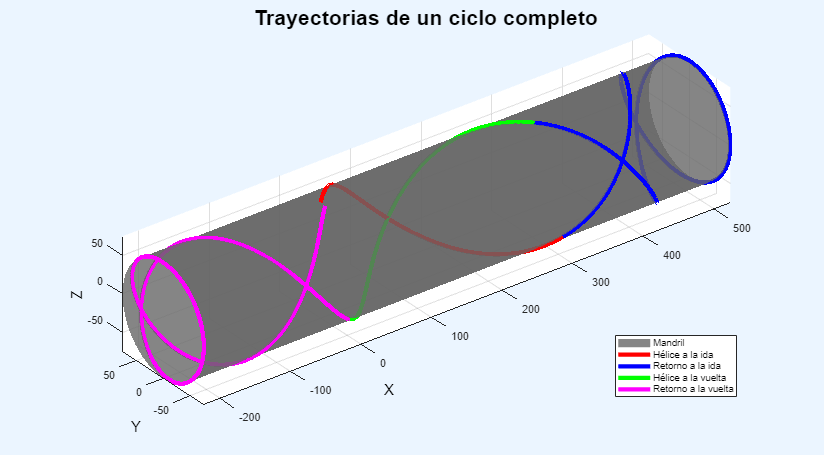

grafica_multiple_7 = struct( ...
    'X1', vector_helice_ida.X, ...
    'Y1', vector_helice_ida.Y, ...
    'Z1', vector_helice_ida.Z, ...
    'X2', vector_retorno_ida.X, ...
    'Y2', vector_retorno_ida.Y, ...
    'Z2', vector_retorno_ida.Z, ...
    'X3', vector_helice_vuelta.X, ...
    'Y3', vector_helice_vuelta.Y, ...
    'Z3', vector_helice_vuelta.Z, ...
    'X4', vector_retorno_vuelta.X, ...
    'Y4', vector_retorno_vuelta.Y, ...
    'Z4', vector_retorno_vuelta.Z);
graficas_multiples(grafica_multiple_7, 'Trayectorias de un ciclo completo', {'Hélice a la ida', 'Retorno a la ida', ...
    'Hélice a la vuelta', 'Retorno a la vuelta'}, var_ini, 'Trayectoria_completa.png'); clear grafica_multiple_7;

## Ciclos para una capa completa:

vector_ciclos = calculo_ciclos(var_ini, vector_calculos_iniciales, vector_mandril, vector_helice_ida, vector_retorno_ida, ...
    vector_helice_vuelta, vector_retorno_vuelta, excel);

## Grafico del un ciclo de cinta de fibra completo:

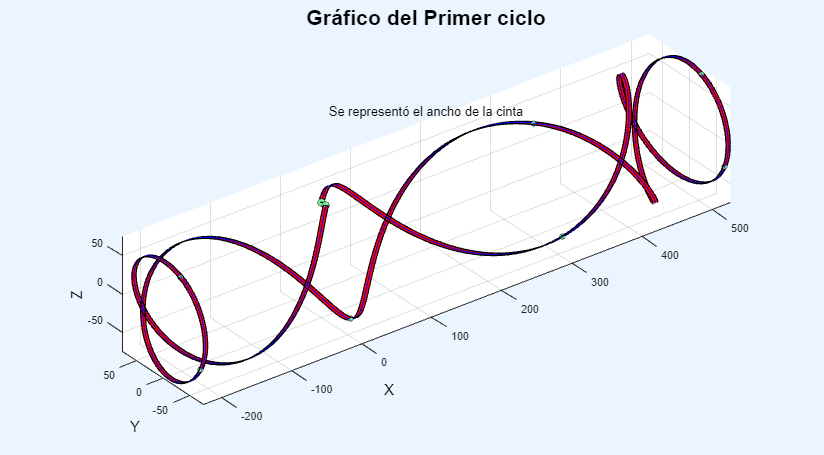

generacion_ciclo_cinta(var_ini, vector_helice_ida, vector_retorno_ida, vector_helice_vuelta, vector_retorno_vuelta, ...
    vector_ciclos);

## CNC

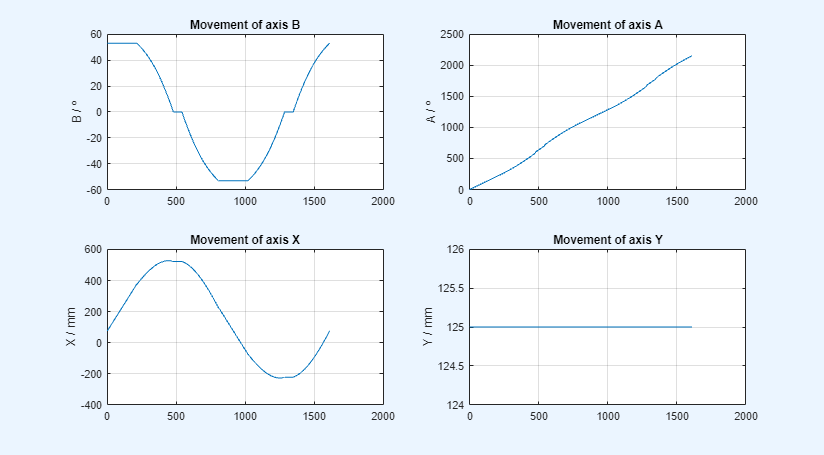

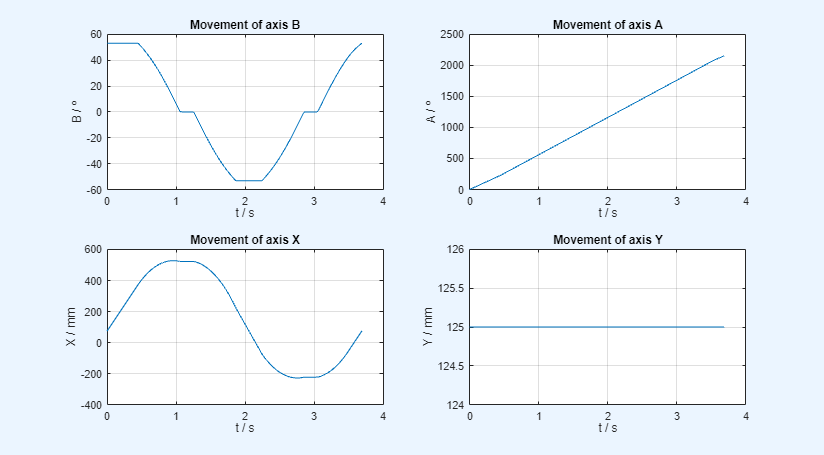

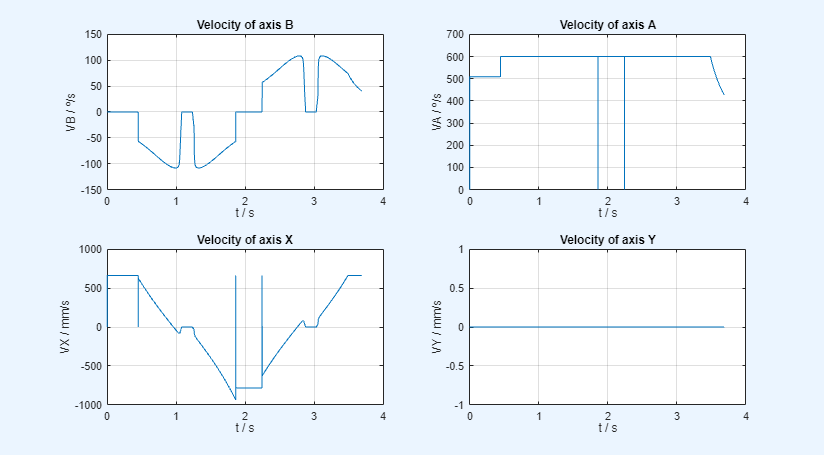

CNC(var_sal, var_ini, var_maq, vector_calculos_iniciales, vector_ciclos);

tiempos_de_calculo.Tiempo_calculo_sin_superposiciones = datetime('now');%Tiempo duración sin las superposiciones
tiempos_de_calculo.Duracion = tiempos_de_calculo.Tiempo_calculo_sin_superposiciones - tiempos_de_calculo.tiempo_de_inicio;
display(tiempos_de_calculo.Duracion);

  duration

   00:03:28



## Superposiciones

vector_nuevo_phi = superposicion_1(var_ini, vector_calculos_iniciales, vector_ciclos, excel);

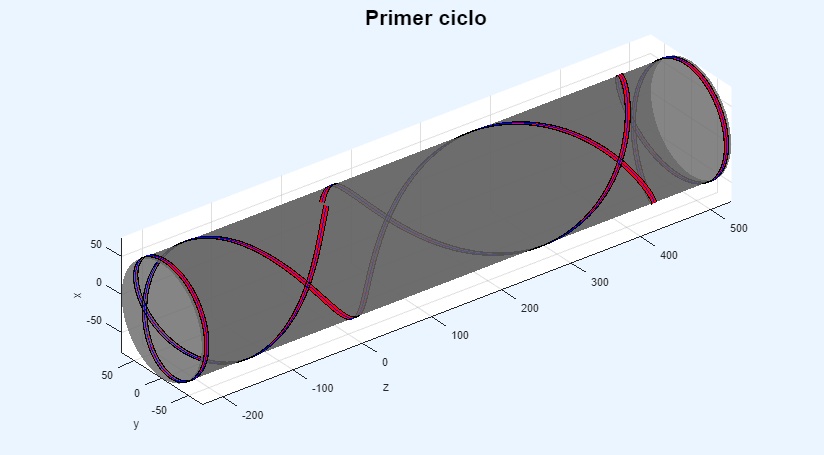

graficar_primer_ciclo(var_ini, vector_calculos_iniciales, vector_mandril, vector_ciclos, 'Gráfico_del_primer_ciclo.png');

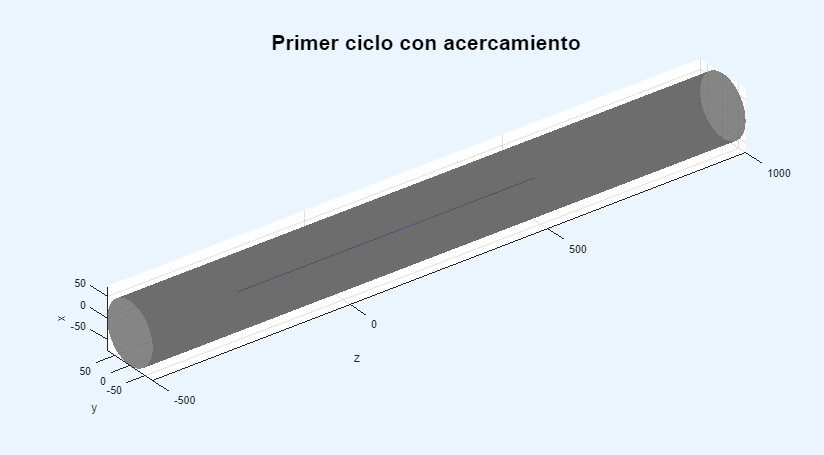

graficar_primer_ciclo2(var_ini, vector_mandril, vector_ciclos, 'Gráfico_del_primer_ciclo2.png');

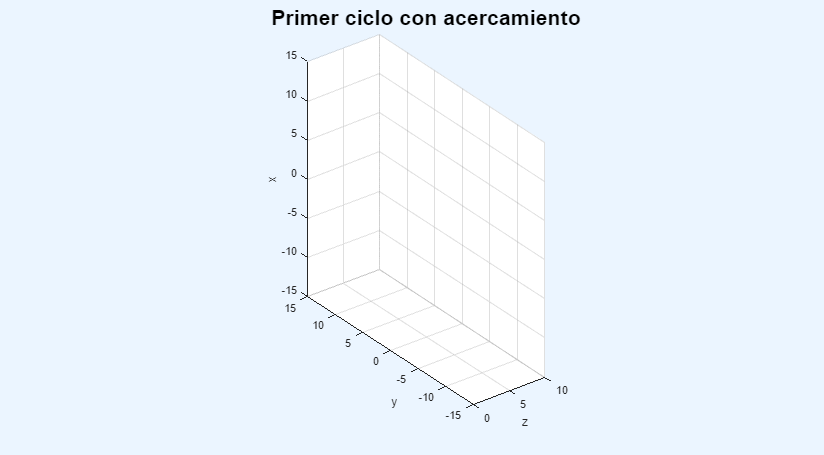

vector_ciclos = graficar_primer_ciclo3(var_ini, vector_calculos_iniciales, vector_mandril, vector_ciclos, 'Gráfico_del_primer_ciclo3.png', excel);

graficar_primer_ciclo4(var_ini, vector_calculos_iniciales, vector_mandril, vector_ciclos);

Unrecognized function or variable 'alfaciclo'.

Error in graficar_primer_ciclo4 (line 84)
                          T = [cos(alfaciclo(1, i)) sin(alfaciclo(1, i)); -sin(alfaciclo(1, i)) cos(alfaciclo(1, i))];


superposicion(var_ini, vector_calculos_iniciales, vector_mandril, vector_ciclos);
tiempos_de_calculo.Tiempo_calculo_con_superposiciones = seconds(datetime('now'));
tiempos_de_calculo.Duracion_superposiciones = tiempos_de_calculo.Tiempo_calculo_con_superposiciones - ...
    tiempos_de_calculo.Tiempo_calculo_sin_superposiciones; %Tiempo duración de superposiciones
tiempos_de_calculo.Duracion_total = tiempos_de_calculo.Tiempo_calculo_con_superposiciones - ...
    tiempos_de_calculo.tiempo_de_inicio; %Tiempo de duración total de calculo